# Optimal Threshold of SVD Recomposition

*Author: Koby Taswell*

First load our file and let's add some noise with the Gaussian Patter

path = 'Kingfisher.jpg';

I = imread(path);

n = max(size(I))

n = 1724

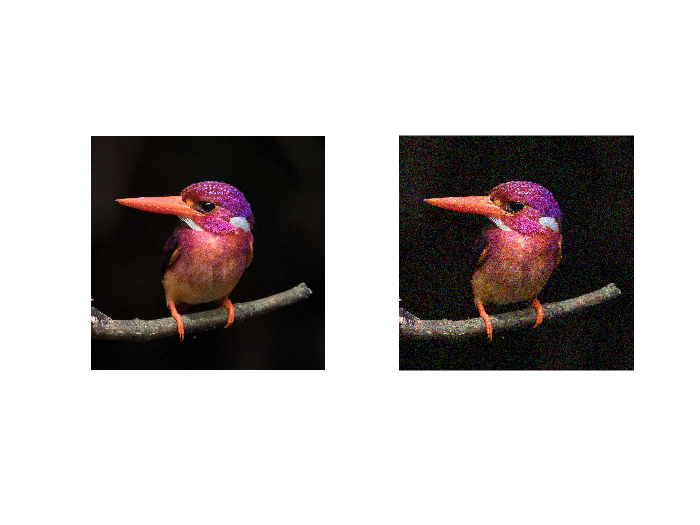


Inoisey = imnoise(I, "gaussian");

clf
subplot(1,2,1)
imshow(I);

subplot(1,2,2)
imshow(Inoisey)

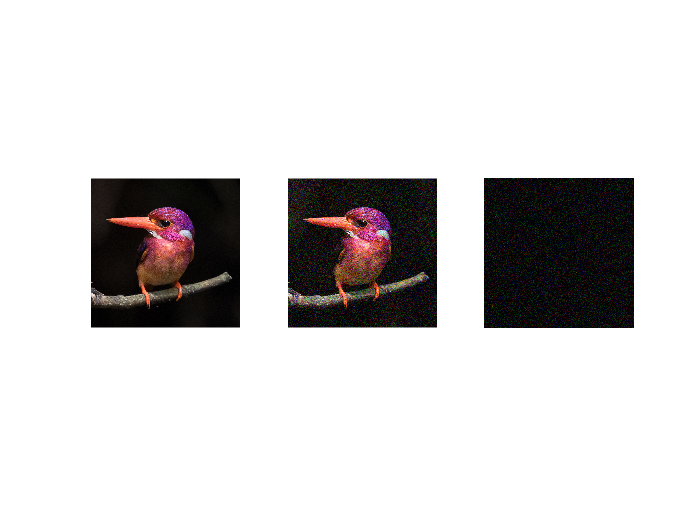

clf
subplot(1,3,1)
imshow(I);

subplot(1,3,2)
imshow(Inoisey)

subplot(1,3,3)
imshow(Inoisey-I)


I = im2double(I);
Inoisey = im2double(Inoisey);

Now let's see how much noise is present in each color channel.

SnR is measured in decibles so 0 means perfect 1:1 ratio of no noise, but anything higher than 1 means there noise is present

noiseRed = snr(I(:, :, 1),Inoisey(:, :, 1)-I(:, :, 1))

noiseRed = 11.1311

noiseGre = snr(I(:, :, 2),Inoisey(:, :, 2)-I(:, :, 2))

noiseGre = 6.8636

noiseBlu = snr(I(:, :, 3),Inoisey(:, :, 3)-I(:, :, 3))

noiseBlu = 7.0508

Let's store this not in decibels but rather in a power ratio:

noiseRed = log10(noiseRed)/10;
noiseGre = log10(noiseGre)/10;
noiseBlu = log10(noiseBlu)/10;

Next we calculate the SVD of each color channel RGB,

[UnoiseyR, SnoiseyR, VnoiseyR] = svd(Inoisey(:, :, 1)); % Red Channel
[UnoiseyG, SnoiseyG, VnoiseyG] = svd(Inoisey(:, :, 2)); % Green Channel
[UnoiseyB, SnoiseyB, VnoiseyB] = svd(Inoisey(:, :, 3)); % Blue Channel

Now we need to find the threshold which will let us find the rank of our approximation.

As defined in Gavish & Donoho 2014, we can find the threshold of an arbitrary n by n matrix as approximately tau = 2.858*median(S)

First find medians of each color channel:

sMedR = median(diag(SnoiseyR)) % Red single values

sMedR = 2.8430

sMedG = median(diag(SnoiseyG)) % Green single values

sMedG = 2.7324

sMedB = median(diag(SnoiseyB)) % Blue single values

sMedB = 2.6740

c = 2.858 % threshold coefficeint

c = 2.8580

tRed = c*sMedR

tRed = 8.1253

tGre = c*sMedG

tGre = 7.8093

tBlu = c*sMedB

tBlu = 7.6423

Set singular values below threshold to zero in each channel

SdenoiseR = SnoiseyR;
SdenoiseG = SnoiseyG;
SdenoiseB = SnoiseyB;

SdenoiseR(SdenoiseR < tRed) = 0;
SdenoiseG(SdenoiseG < tGre) = 0;
SdenoiseB(SdenoiseB < tBlu) = 0;

Reconstruct each matrix

DenoisedRed = UnoiseyR*SdenoiseR*VnoiseyR.';
DenoisedGre = UnoiseyG*SdenoiseG*VnoiseyG.';
DenoisedBlu = UnoiseyB*SdenoiseB*VnoiseyB.';

Idenoised = cat(3, DenoisedRed, DenoisedGre, DenoisedBlu);

Display for Visual Assessment

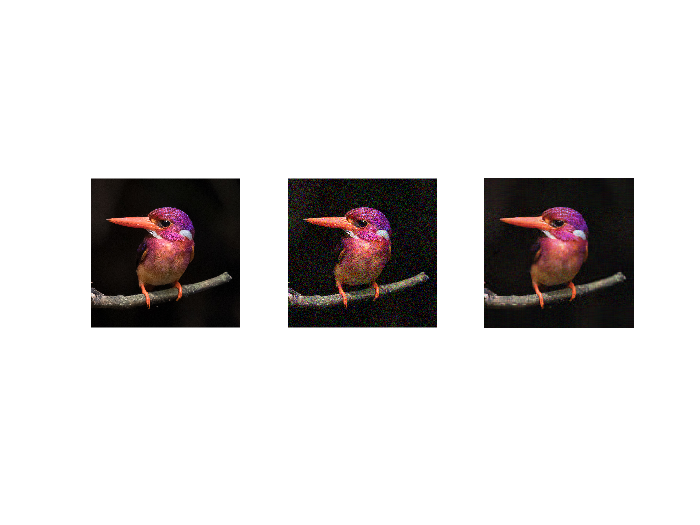

clf
subplot(1,3,1)
imshow(I)

subplot(1,3,2)
imshow(Inoisey)

subplot(1,3,3)
imshow(Idenoised)

Now we calculate new signal to noise ratio:

noiseDeArbRed = snr(I(:, :, 1),Idenoised(:, :, 1)-I(:, :, 1))

noiseDeArbRed = 15.5708

noiseDeArbGre = snr(I(:, :, 2),Idenoised(:, :, 2)-I(:, :, 2))

noiseDeArbGre = 12.3681

noiseDeArbBlu = snr(I(:, :, 3),Idenoised(:, :, 3)-I(:, :, 3))

noiseDeArbBlu = 11.7616

We can also look at other signal to noise metrics:

The mean square error 

ImseNoise = immse(I, Inoisey)

ImseNoise = 0.0066

ImseDenoise = immse(I, Idenoised)

ImseDenoise = 0.0022

Another method of measuring the perfromance of the matrix reconstruction is to caclulate the Frobenius Distance between the two signals (Shablin and Nobel). 

RedDistance = norm(I(:, :, 1)-Idenoised(:, :, 1),'fro');
BluDistance = norm(I(:, :, 2)-Idenoised(:, :, 2),'fro');
GreDistance = norm(I(:, :, 3)-Idenoised(:, :, 3),'fro');
FroDistance = (RedDistance + BluDistance + GreDistance) / 3

FroDistance = 79.9813

Let's test to see if we can use the direct estimation via known values of noise for our square matrix.

Recall our existing signal to noise ratios for each channel, then apply optimal hard thresholding with more direct estimation via square matricies

disp(noiseRed)

    0.1046



disp(noiseGre)

    0.0836



disp(noiseBlu)

    0.0849



d = (4/sqrt(3));

tRedSq = d*sqrt(n)*noiseRed;
tGreSq = d*sqrt(n)*noiseGre;
tBluSq = d*sqrt(n)*noiseBlu;

Now apply our new thresholds

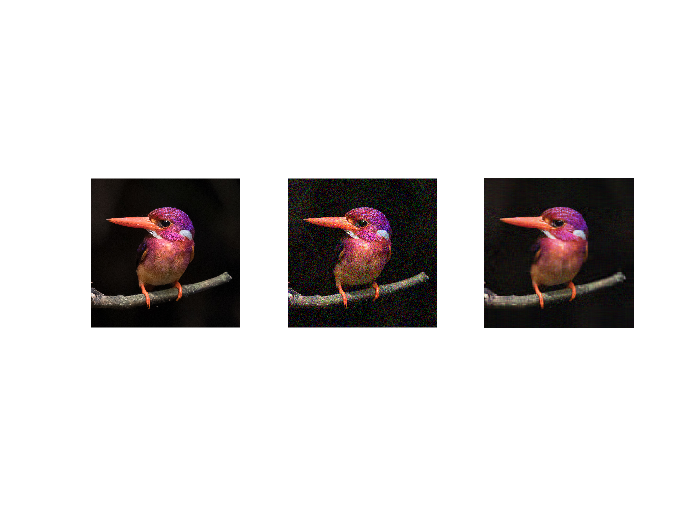

SdenoiseRsq = SnoiseyR;
SdenoiseGsq = SnoiseyG;
SdenoiseBsq = SnoiseyB;

SdenoiseRsq(SdenoiseRsq < tRedSq) = 0;
SdenoiseGsq(SdenoiseGsq < tGreSq) = 0;
SdenoiseBsq(SdenoiseBsq < tBluSq) = 0;

DenoisedRed = UnoiseyR*SdenoiseRsq*VnoiseyR.';
DenoisedGre = UnoiseyG*SdenoiseGsq*VnoiseyG.';
DenoisedBlu = UnoiseyB*SdenoiseBsq*VnoiseyB.';

IdenoisedSq = cat(3, DenoisedRed,DenoisedGre, DenoisedBlu);

clf
subplot(1,3,1)
imshow(I);

subplot(1,3,2)
imshow(Inoisey);

% subplot(2,2,3)
% imshow(Idenoised);

subplot(1,3,3)
imshow(IdenoisedSq)

Let's see how much noise is left after denoising

noiseDeSqRed = snr(I(:, :, 1),IdenoisedSq(:, :, 1) - I(:,:,1))

noiseDeSqRed = 15.3444

noiseDeSqGre = snr(I(:, :, 2),IdenoisedSq(:, :, 2) - I(:,:,2))

noiseDeSqGre = 12.3539

noiseDeSqBlu = snr(I(:, :, 3),IdenoisedSq(:, :, 3) - I(:,:,3))

noiseDeSqBlu = 11.7583


ImseDoubleDenoiseSq = immse(I, IdenoisedSq)

ImseDoubleDenoiseSq = 0.0022

Now lets calculate the Frobenius distance. . 

RedDistance = norm(I(:, :, 1)-IdenoisedSq(:, :, 1),'fro');
BluDistance = norm(I(:, :, 2)-IdenoisedSq(:, :, 2),'fro');
GreDistance = norm(I(:, :, 3)-IdenoisedSq(:, :, 3),'fro');
FroDistance = (RedDistance + BluDistance + GreDistance) / 3

FroDistance = 80.7819

We can see that the hard thresholding for arbitrary noise performs better than the direct estimation with known noise.  

Finally lets see how Bulk Edge thresholding performs.

Recall our existing Signal-noise-ratios for each color channel:

disp(noiseRed)

    0.1046



disp(noiseGre)

    0.0837



disp(noiseBlu)

    0.0849



Get beta where beta = m/n

[m,n,dim] = size(I);
beta = m/n

beta = 1

According to Gavish & Donoho 2014, the distribution of singular values will form a quarter circle bulk which lies at (1+sqrt(beta) * sqrt(n) * noise 

t = 1+sqrt(beta)

t = 2

tRedBulk = t*sqrt(n)*noiseRed;
tGreBulk = t*sqrt(n)*noiseGre;
tBluBulk = t*sqrt(n)*noiseBlu;

apply thresholds and reconstruct

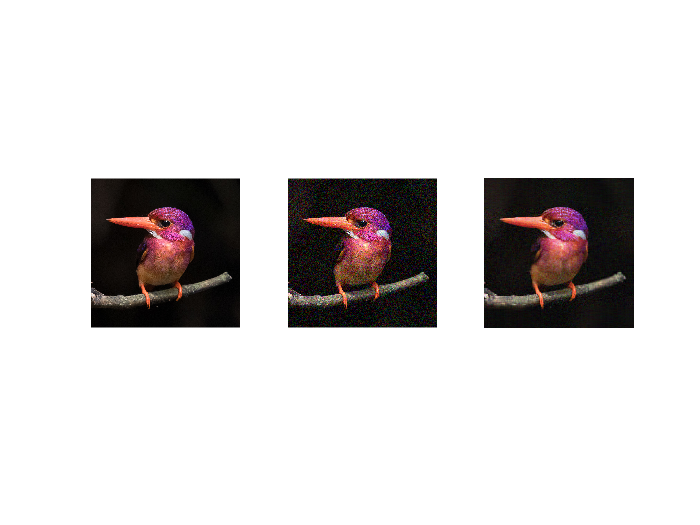

SdenoiseRbulk = SnoiseyR;
SdenoiseGbulk = SnoiseyG;
SdenoiseBbulk = SnoiseyB;


SdenoiseRbulk(SdenoiseRbulk < tRedBulk) = 0;
SdenoiseGbulk(SdenoiseGbulk < tGreBulk) = 0;
SdenoiseBbulk(SdenoiseBbulk < tBluBulk) = 0;

DenoisedRed = UnoiseyR*SdenoiseRbulk*VnoiseyR.';
DenoisedGre = UnoiseyG*SdenoiseGbulk*VnoiseyG.';
DenoisedBlu = UnoiseyB*SdenoiseBbulk*VnoiseyB.';

IdenoiseBulk = cat(3, DenoisedRed,DenoisedGre, DenoisedBlu);

clf
subplot(1,3,1)
imshow(I);

subplot(1,3,2)
imshow(Inoisey);

% subplot(2,2,3)
% imshow(Idenoised);

subplot(1,3,3)
imshow(IdenoiseBulk)

Calculate MSE

ImseDoubleDenoiseBulk = immse(I, IdenoiseBulk)

ImseDoubleDenoiseBulk = 0.0022

RedDistance = norm(I(:, :, 1)-IdenoiseBulk(:, :, 1),'fro');
BluDistance = norm(I(:, :, 2)-IdenoiseBulk(:, :, 2),'fro');
GreDistance = norm(I(:, :, 3)-IdenoiseBulk(:, :, 3),'fro');
FroDistance = (RedDistance + BluDistance + GreDistance) / 3

FroDistance = 81.1171

noiseDeBulkRed = snr(I(:, :, 1),IdenoiseBulk(:, :, 1) - I(:,:,1))

noiseDeBulkRed = 15.5387

noiseDeBulkGre = snr(I(:, :, 2),IdenoiseBulk(:, :, 2) - I(:,:,2))

noiseDeBulkGre = 12.1211

noiseDeBulkBlu = snr(I(:, :, 3),IdenoiseBulk(:, :, 3) - I(:,:,3))

noiseDeBulkBlu = 11.6600

We see that bulk edge thresholding performs just as well as the square matrix estimation with known noise described in Gavish & Donoho 2014.

To investigate this, let's take a look at the number of singular values each of the square matrix estimation and bulk edge thresholding remove.

sRed = diag(SnoiseyR);
sGre = diag(SnoiseyG);
sBlu = diag(SnoiseyB);

sRemovedR = sum(sRed < tRed);
sRemovedG = sum(sGre < tGre);
sRemovedB = sum(sBlu < tBlu);
sRemovedSqR = sum(sRed < tRedSq);
sRemovedSqG = sum(sGre < tGreSq);
sRemovedSqB = sum(sBlu < tBluSq);
sRemovedBulkR = sum(sRed < tRedBulk);
sRemovedBulkG = sum(sGre < tGreBulk);
sRemovedBulkB = sum(sBlu < tBluBulk);
sRemovedMat = [sRemovedR, sRemovedSqR, sRemovedBulkR;
            sRemovedG, sRemovedSqG, sRemovedBulkG;
            sRemovedB, sRemovedSqG, sRemovedBulkB]

sRemovedMat =         1669        1691        1680
        1678        1681        1653
        1669        1681        1649


sKeptMat = n*ones(3,3) - sRemovedMat

sKeptMat =     55    33    44
    46    43    71
    55    43    75


It appears as if the arbitrary removal method is a much lower rank approximation as opposed to either method which utilizes a known signal to noise ratio. 